# Time evolution for a DAE system on a star graph

Evolves the linear Schrodinger equation through time.

## Set up the graph structure and coordinates of the problem

By default, the discretization type is uniform but you may choose it to be Chebyshev for the time evolution. You can also set other properties such as the number of discretization points per edge.

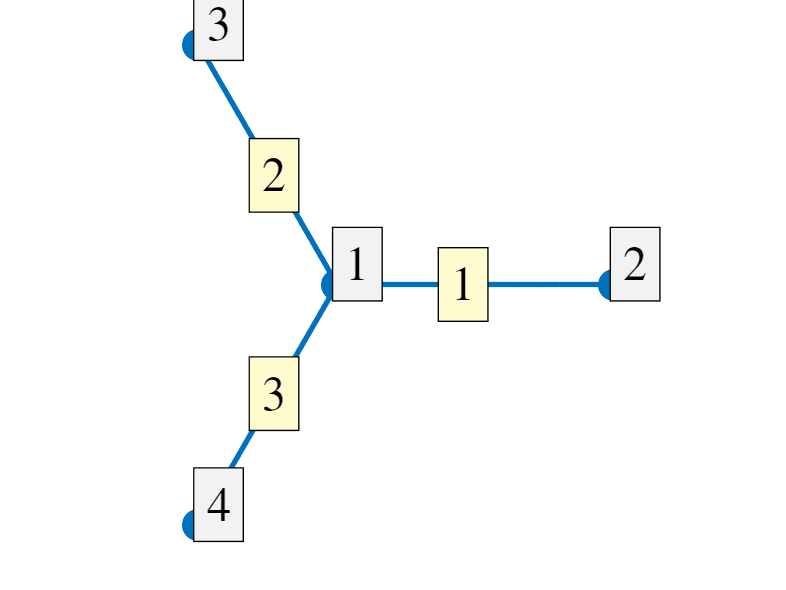

Phi = quantumGraphFromTemplate('star','discretization','Chebyshev','nX',16);
Phi.plot('layout')

## Define the function

Define the linear Schrodinger time equation on Phi.

A = Phi.laplacianMatrix;  % The second spatial derivative operator
f = @(t,z) 1i * A*z;

## Time evolution

You need an initial condition, step size, how long the program should run till and the scheme type you desire. Right now, we have 2nd, 4th and 8th order schemes. For this example, I put a soliton on one of the edges of the star graph and propogated it towards the junction.

xgrid = pi*chebptsSecondKind(16)';
u0 = [zeros(1,18) -exp(1i*xgrid)+1 zeros(1,18)]';
tend = 5;
% [u,t] = Phi.timeEvolveDAE(f,u0,deltat,tend,8);
[t,u] = Phi.timeEvolveDH(f,u0,tend);

## Plotting the solution

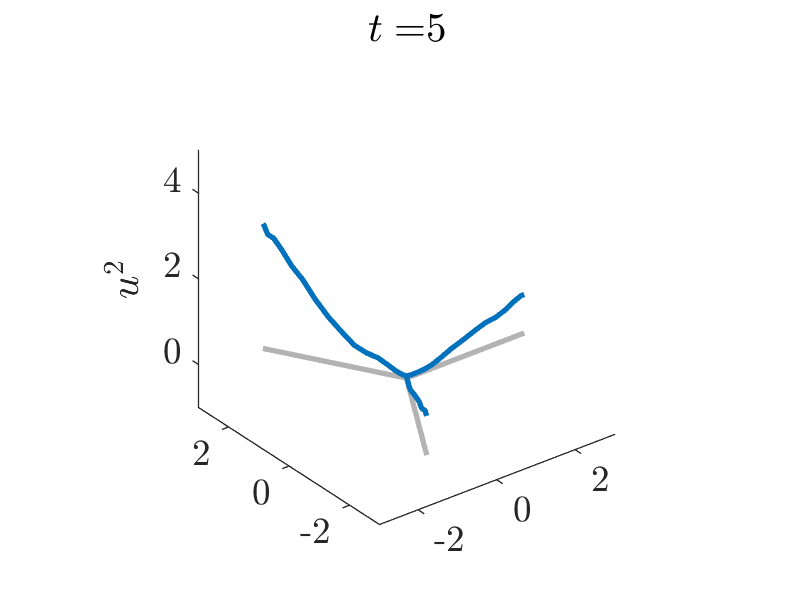

n = size(u,2);
scale = floor(n/1000);
for i=1:floor(n/scale)
    clf
    Phi.plot(abs(u(:,scale*i)).^2)
    axis([-3 3 -3 3 -1 5])
    daspect([1 1 1])
    title(['$t=$',num2str(round(t(scale*i),2))])
    zlabel('$u^2$')
    pause(.0000000001)
end


% scale = 5000;
% fignum = 1;
% for i=1:size(u,2)/scale
%     figure(fignum)
%     Phi.plot(abs(u(:,scale*i)).^2)
%     title(['$t=$',num2str( t(scale*i) )])
%     axis([-3 3 -3 3 -1 5])
%     daspect([1 1 1])
%     zlabel('$u^2$')
%     pause(.000000001)
%     
%     filename = 'starTimeEvol.gif';
%     del = 0.01; % time between animation frames
%     drawnow 
%     frame = getframe(fignum);
%     im = frame2im(frame);
%     [imind,cm] = rgb2ind(im,256);
%     if i == 1
%         imwrite(imind,cm,filename,'gif','Loopcount',inf,'DelayTime',del);
%     else
%         imwrite(imind,cm,filename,'gif','WriteMode','append','DelayTime',del);
%     end
%     fignum = fignum + 1;
%     close all
% end

## Saving Visual Data

Setting the path

% 

Generating lots of PNG's

% for i=1:5%size(u,2)/scale
%     Phi.plot(abs(u(:,scale*i)).^2)
%     title(['$t=$',num2str( t(scale*i) )])
%     axis([-3 3 -3 3 -1 5])
%     daspect([1 1 1])
%     zlabel('$u^2$')
%     pause(.000000001)
%     
%     filename = ['Fig_',num2str(i),'.png'];
%     ax=gca;
%     exportgraphics(ax,sprintf('FIG_%d.png',i));
%     close all
% end

Generating a GIF

% for fignum=1:size(u,2)/scale
%     figure(fignum)
%     Phi.plot(abs(u(:,scale*i)).^2)
%     title(['$t=$',num2str( t(scale*i) )])
%     axis([-3 3 -3 3 -1 5])
%     daspect([1 1 1])
%     zlabel('$u^2$')
%     pause(.000000001)
%     
%     filename = 'starTimeEvol.gif';
%     del = 0.01; % time between animation frames
%     drawnow 
%     frame = getframe(fignum);
%     im = frame2im(frame);
%     [imind,cm] = rgb2ind(im,256);
%     if i == 1
%         imwrite(imind,cm,filename,'gif','Loopcount',inf,'DelayTime',del);
%     else
%         imwrite(imind,cm,filename,'gif','WriteMode','append','DelayTime',del);
%     end
%     fignum = fignum + 1;
%     close all
% end

## Saving and loading the data

Save data

% save('star_nx16_h10neg5.mat','u');

Load data

% savedmat=matfile('star_nx16_h10neg5').u;

## Error Analysis

Check for conservation of energy and mass.

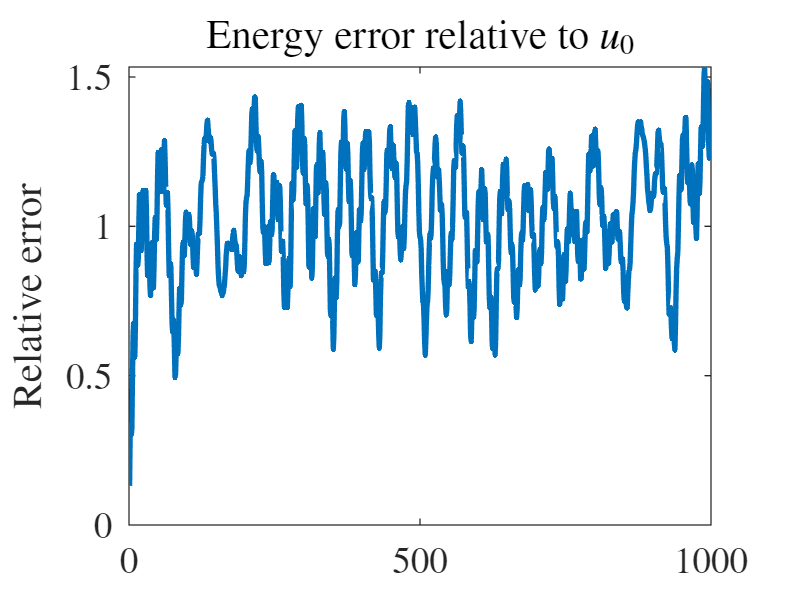

energyDiff = zeros(floor(n/scale),1);
massDiff = zeros(floor(n/scale),1);
tplot = zeros(floor(n/scale),1);
u0energy = 0.5*Phi.dot( A*u(:,1) , conj(u(:,1)) );
u0mass = Phi.dot(u(:,1),conj(u(:,1)));

for i=1:floor(n/scale)
    ui = u(:,scale*i);
    energyDiff(i) = abs( (0.5*Phi.dot(A*ui,conj(ui)) - u0energy) / u0energy );
    massDiff(i) = abs( (Phi.dot(ui,conj(ui)) - u0mass) / u0mass );
    tplot(i) = t(scale*i);
end

disp('')
plot(energyDiff)
title('Energy error relative to $u_0$')
ylabel('Relative error')

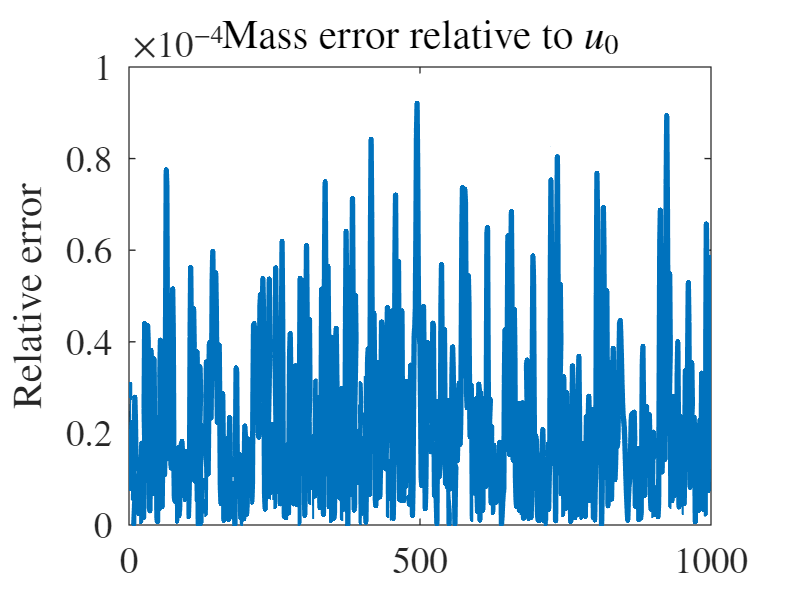

figure
plot(massDiff)
title('Mass error relative to $u_0$')
ylabel('Relative error')